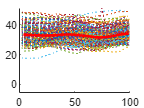

figure
hold on
bigx=[];
bigy=[];
for i=1:length(output)
    try
        x = output(i).BackAngle.f.avg;
        y = output(i).BackAngle.y.avg;
        bigy(i,:) = y;
        bigx(i,:) = x;
        plot(x,y,':')
    end
end
bigx(bigx==0)=nan;
bigy(bigy==0)=nan;

avx = mean(bigx, 'omitnan');
avy = mean(bigy, 'omitnan');
plot(avx,avy,'LineWidth',2,'Color','red')